EE3510 HW4 105060012張育菘

Consider a unity feedback control system with Gc(s)=K and R(s)=0 for inverted pendulum (example 3.3) in textbook.

Analyze C = [0,0,1,0],[0,0,1,1] and [0,1,1,1] and different K.


$$A=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & -\frac{\;\mathrm{mg}\;}{M} & 0\\
0 & 0 & 0 & 1\\
0 & 0 & \frac{\;g\;}{l} & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
\frac{1}{M}\\
0\\
-\frac{1}{\;\mathrm{Ml}\;}
\end{array}\right\rbrack$$



$$\dot{x} \left(t\right)=\mathrm{Ax}\left(t\right)+\mathrm{Bu}\left(t\right),y\left(t\right)=\mathrm{Cx}\left(t\right)+\mathrm{Du}\left(t\right)$$


1) use Simulink to simulate the output response for different K in s-domain.

close all; clear;

% initial parameter
g = 9.8; l = 0.5; m = 0.01; M = 2;

% system matrix
A = [0 1 0 0; 0 0 -m*g/M 0; 0 0 0 1; 0 0 g/l 0;];
B = [0; 1/M; 0; -1/(M*l)];
C1 = [0 0 1 0]; C2 = [0 0 1 1]; C3 = [0 1 1 1];
D = [0];
K = -36; % K = -18, -36, -100

[num1, den1] = ss2tf(A,B,C1,D)

num1 =          0         0   -1.0000    0.0000    0.0000


den1 =     1.0000         0  -19.6000         0         0


[num2, den2] = ss2tf(A,B,C2,D)

num2 =          0   -1.0000   -1.0000         0         0


den2 =     1.0000         0  -19.6000         0         0


[num3, den3] = ss2tf(A,B,C3,D)

num3 =          0   -0.5000   -1.0000   -9.7510         0


den3 =     1.0000         0  -19.6000         0         0


2) use ode45 to simulate the output response for different K in time -domain. 

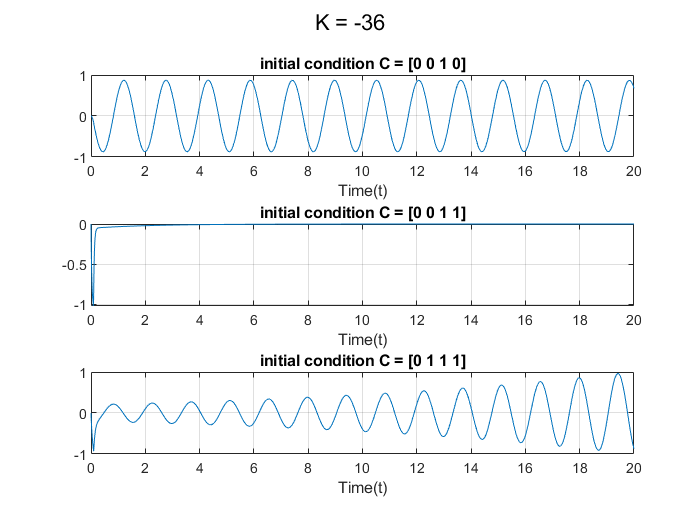

close all; clear;

tspan = [0 20]; % time interval from 0 ~ 20
iniCon = [0; 0; 0; 0;]; % initial condition

C1 = [0 0 1 0]; C2 = [0 0 1 1]; C3 = [0 1 1 1];
K1 = -36;   K2 = -18;   K3 = -100;

[t1, x1] = ode45(@(t, x) sysf(t, x, C1, K1), tspan, iniCon);
[t2, x2] = ode45(@(t, x) sysf(t, x, C2, K1), tspan, iniCon);
[t3, x3] = ode45(@(t, x) sysf(t, x, C3, K1), tspan, iniCon);

y1 = C1.*x1;
y2 = C2.*x2;
y3 = C3.*x3;

y1_a = y1(:, 1) + y1(:, 2) + y1(:, 3) + y1(:, 4);
y2_a = y2(:, 1) + y2(:, 2) + y2(:, 3) + y2(:, 4);
y3_a = y3(:, 1) + y3(:, 2) + y3(:, 3) + y3(:, 4);

figure; sgtitle('K = -36');
subplot(3, 1, 1); plot(t1, y1_a); grid on;
title('initial condition C = [0 0 1 0]');
xlabel('Time(t)'); 
subplot(3, 1, 2); plot(t2, y2_a); grid on;
title('initial condition C = [0 0 1 1]');
xlabel('Time(t)'); 
subplot(3, 1, 3); plot(t3, y3_a); grid on;
title('initial condition C = [0 1 1 1]');
xlabel('Time(t)'); 

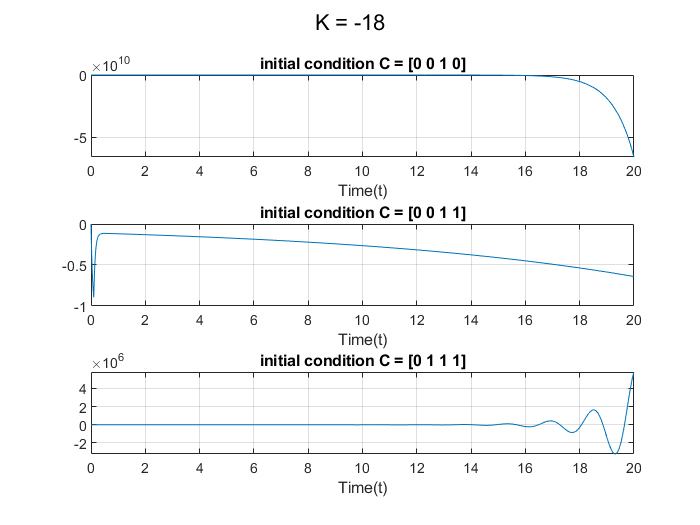


[t1, x1] = ode45(@(t, x) sysf(t, x, C1, K2), tspan, iniCon);
[t2, x2] = ode45(@(t, x) sysf(t, x, C2, K2), tspan, iniCon);
[t3, x3] = ode45(@(t, x) sysf(t, x, C3, K2), tspan, iniCon);

y1 = C1.*x1;
y2 = C2.*x2;
y3 = C3.*x3;

y1_a = y1(:, 1) + y1(:, 2) + y1(:, 3) + y1(:, 4);
y2_a = y2(:, 1) + y2(:, 2) + y2(:, 3) + y2(:, 4);
y3_a = y3(:, 1) + y3(:, 2) + y3(:, 3) + y3(:, 4);

figure; sgtitle('K = -18');
subplot(3, 1, 1); plot(t1, y1_a); grid on;
title('initial condition C = [0 0 1 0]');
xlabel('Time(t)'); 
subplot(3, 1, 2); plot(t2, y2_a); grid on;
title('initial condition C = [0 0 1 1]');
xlabel('Time(t)'); 
subplot(3, 1, 3); plot(t3, y3_a); grid on;
title('initial condition C = [0 1 1 1]');
xlabel('Time(t)'); 

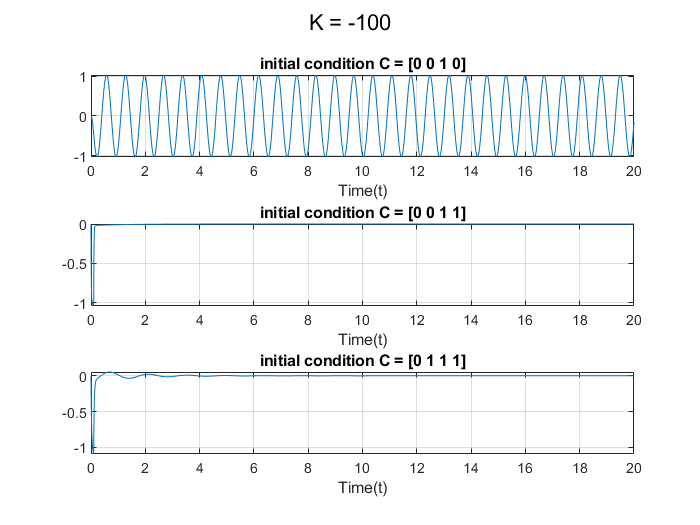


[t1, x1] = ode45(@(t, x) sysf(t, x, C1, K3), tspan, iniCon);
[t2, x2] = ode45(@(t, x) sysf(t, x, C2, K3), tspan, iniCon);
[t3, x3] = ode45(@(t, x) sysf(t, x, C3, K3), tspan, iniCon);

y1 = C1.*x1;
y2 = C2.*x2;
y3 = C3.*x3;

y1_a = y1(:, 1) + y1(:, 2) + y1(:, 3) + y1(:, 4);
y2_a = y2(:, 1) + y2(:, 2) + y2(:, 3) + y2(:, 4);
y3_a = y3(:, 1) + y3(:, 2) + y3(:, 3) + y3(:, 4);

figure; sgtitle('K = -100');
subplot(3, 1, 1); plot(t1, y1_a); grid on;
title('initial condition C = [0 0 1 0]');
xlabel('Time(t)'); 
subplot(3, 1, 2); plot(t2, y2_a); grid on;
title('initial condition C = [0 0 1 1]');
xlabel('Time(t)'); 
subplot(3, 1, 3); plot(t3, y3_a); grid on;
title('initial condition C = [0 1 1 1]');
xlabel('Time(t)'); 


function dx = sysf(t, x, C, K)
    % initial parameter
    g = 9.8; l = 0.5; m = 0.01; M = 2;
    
    pulse = rectangularPulse(0, 0.1, t);
    
    % system matrix
    A = [0 1 0 0; 0 0 -m*g/M 0; 0 0 0 1; 0 0 g/l 0;];
    B = [0; 1/M; 0; -1/(M*l)];
    
    C_a = C*x;

    Gc = (0-(C_a+pulse))*K;
    u = Gc*heaviside(t);
    dx = A*x + B*u;
end
